clc; clearvars; close all;

cd(fileparts(matlab.desktop.editor.getActiveFilename)); % Changes folder to current file location
stilPath = 'stiletto_bag_files/';
addpath(genpath(stilPath))    % Adds all functions to PATH for ease of use

## Cycle folders

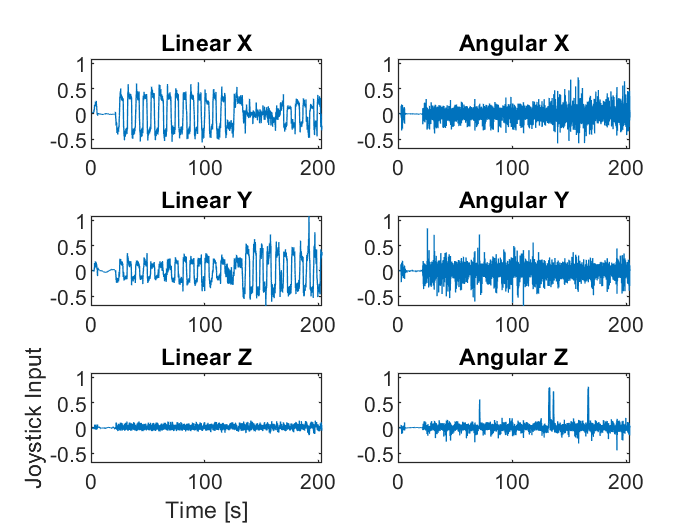

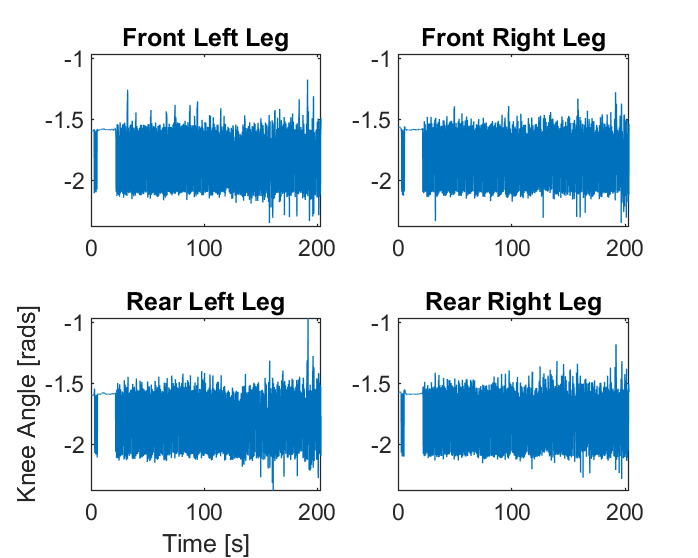

Error using openFigure
The value of 'Filename' is invalid. It must satisfy the function: ischar.

Error in openfig>localGetFileAndOptions (line 104)
ip.parse(args{:});

Error in openfig (line 37)
[filename, reuse, visibleActi

stilTests  = dir(stilPath);
numCSVs = 0;

for f = 8:9    % skips "." and ".." from dir()
% for f = 3:size(dir(stilPath),1)    % skips "." and ".." from dir()
    folderInfo = stilTests(f);
    testFolderPath = strcat(folderInfo.folder, '\',folderInfo.name,'\');
    
    JSFiles   = dir(strcat(testFolderPath,'*joint_states.csv'));
    OdoFiles  = dir(strcat(testFolderPath,'*twist.csv'));
    FeetFiles = dir(strcat(testFolderPath,'*feet.csv'));

    numCSVs = numCSVs + size(JSFiles,1);
        
    for i = 1:size(JSFiles,1)
        JSFilePath   = strcat(JSFiles(i).folder,  '\',  JSFiles(i).name);
        OdoFilePath  = strcat(OdoFiles(i).folder, '\', OdoFiles(i).name);
        FeetFilePath = strcat(FeetFiles(i).folder,'\',FeetFiles(i).name);
        
        plot_stiletto_jointStates(JSFilePath, OdoFilePath, FeetFilePath)
    end
end